# Clustersize Inference Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path. To do so you can navigate to the StatBainz folder and fun the function addSB2path.m. Alternatively you can fill in the directory and run the code below.

statsbrainz_directory_pathloc = 'fill me in';
addpath(genpath(statsbrainz_directory_pathloc));

Load in the mask:

figure; set(gcf,'Visible','on')
mask = imgload('MNImask');
viewbrain( mask, [30,40,40] )

ans =   Axes with properties:

             XLim: [0.5000 264.5000]
             YLim: [0.5000 90.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 1 1]
            Units: 'normalized'

  Show all properties

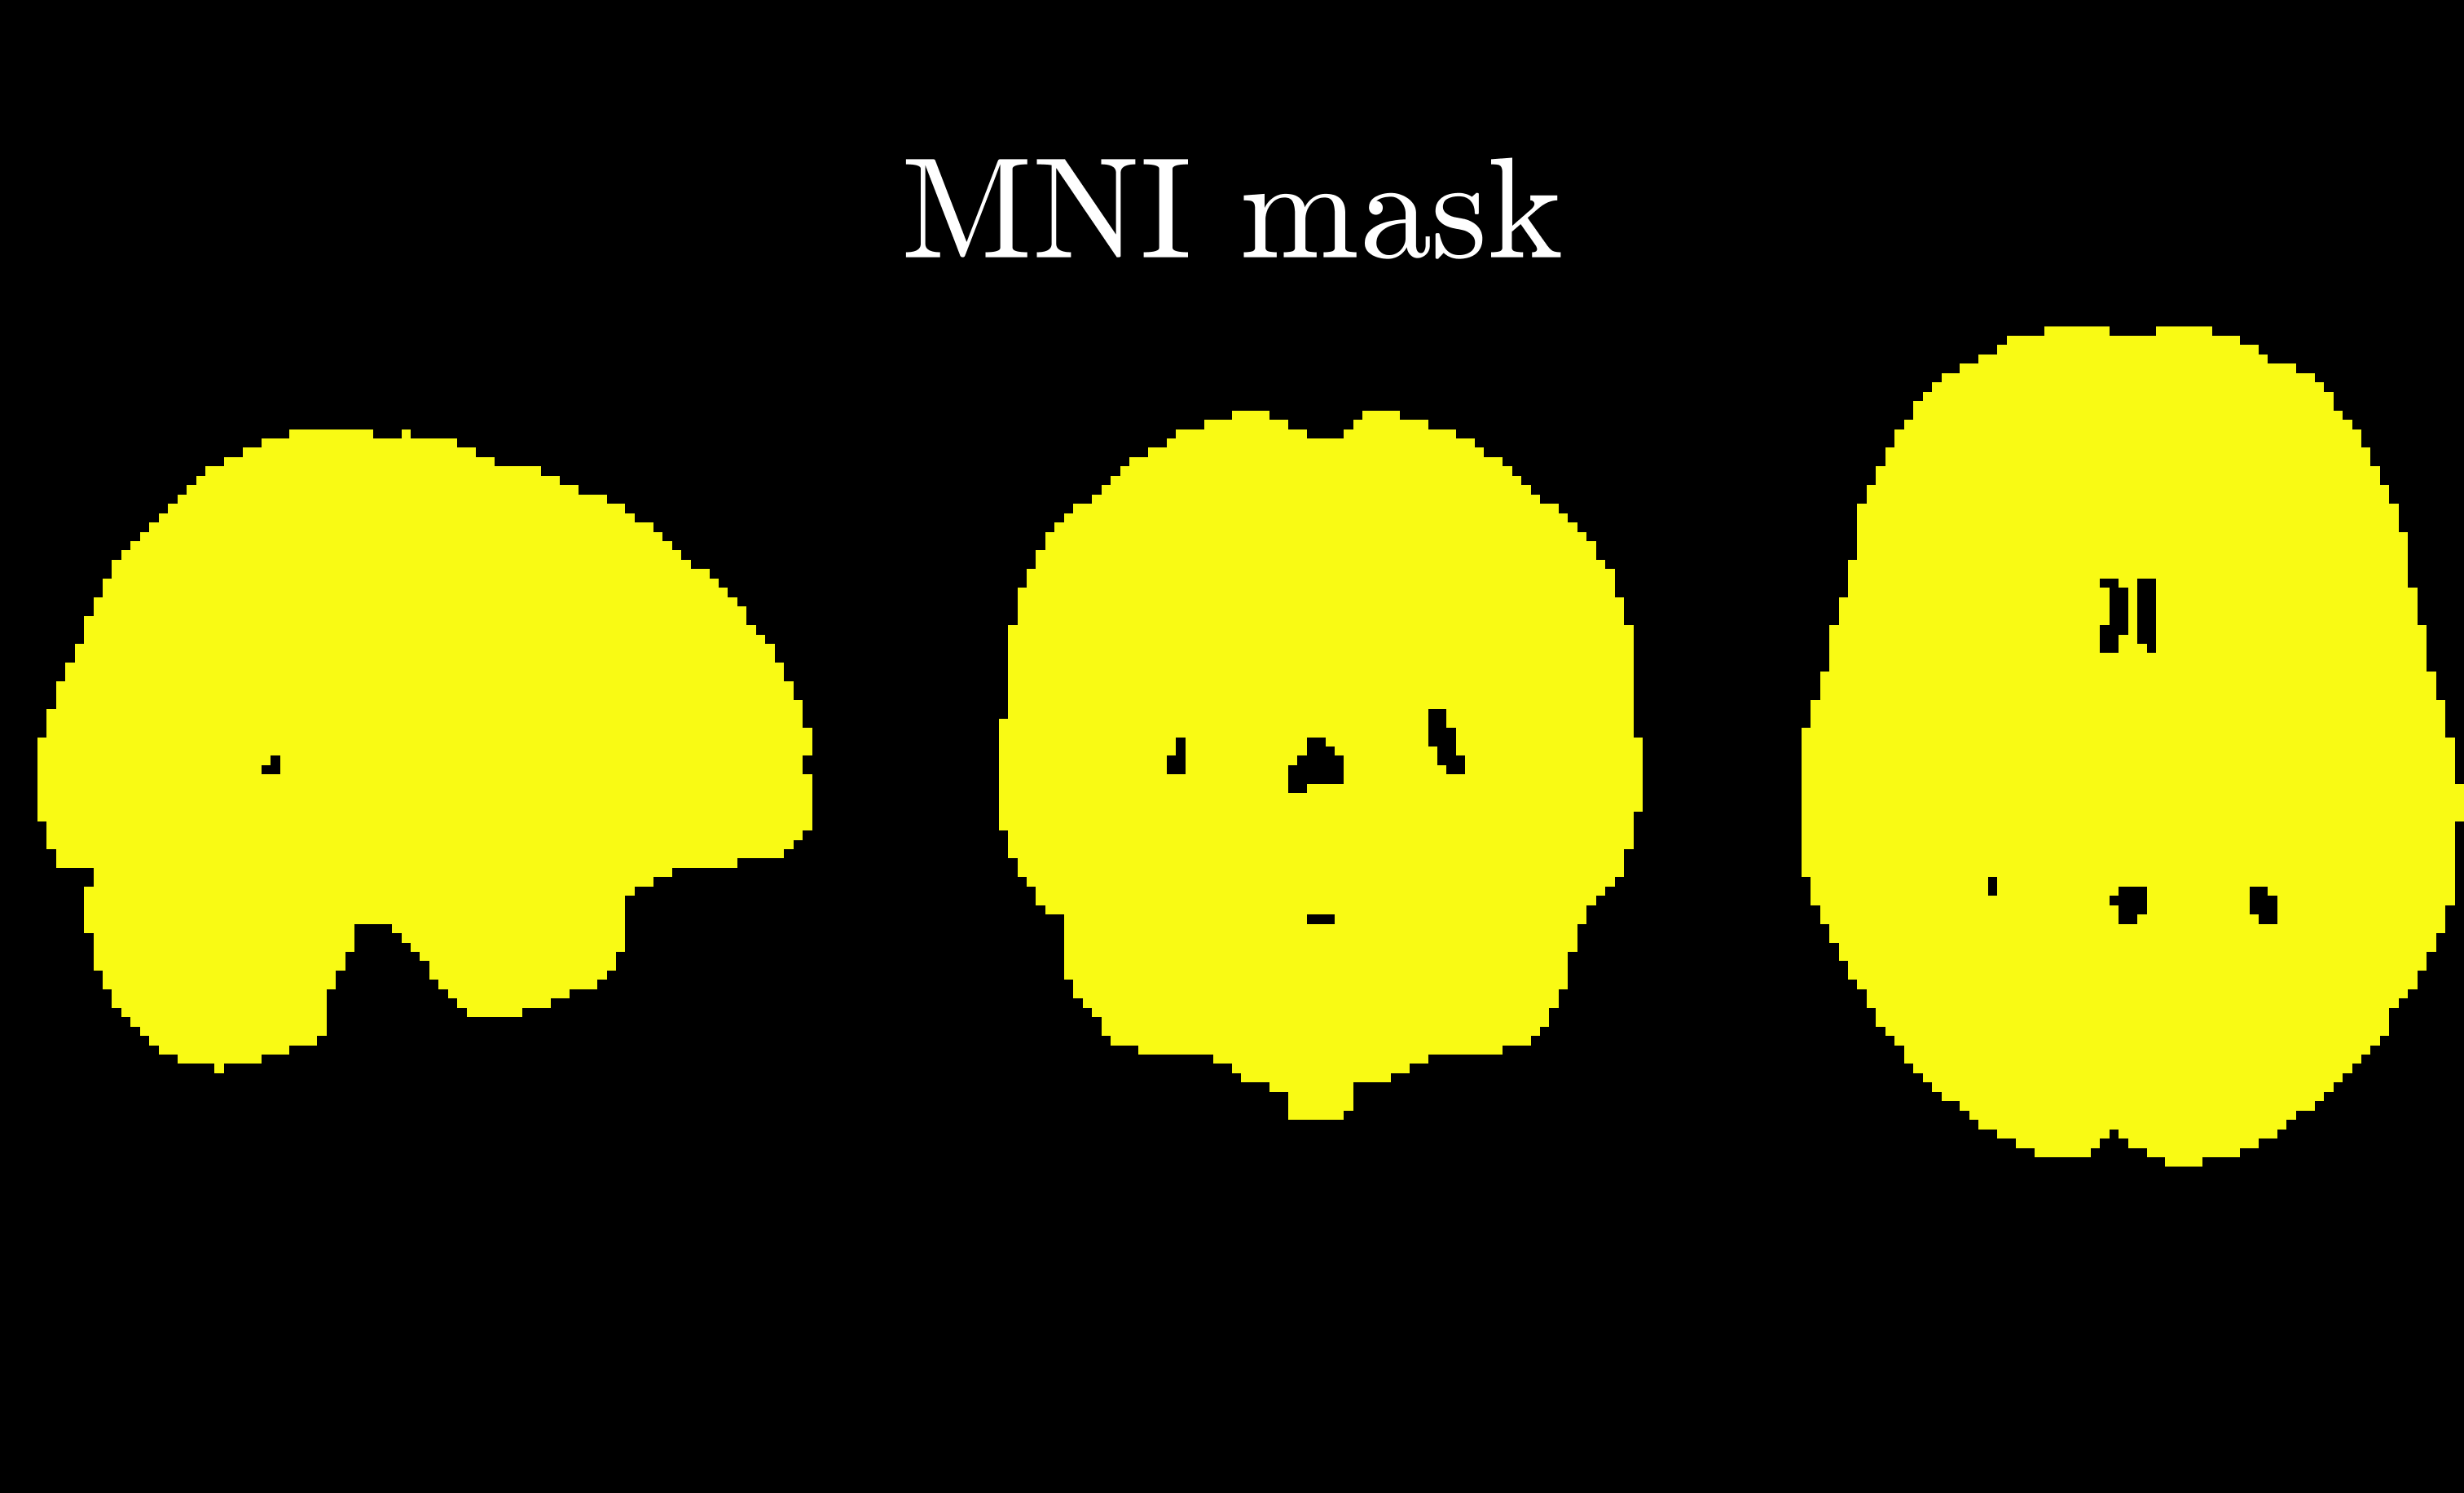

title('    MNI mask', 'Color','white')
BigFont(80)
axis off

#### Generate realistic data

The mean and standard-deviation of processed first level imaging data from 4000 subjects from the UK Biobank is available in the file /BrainImages/Real_data/ukb.mat. These subjects peformed a faces-shape task and the avaiable images are the the processed constrast maps corresponding to the difference between the faces and the shapes conditions. The images have been smoothed with a FWHM of 3mm. We will use these summary statistics to generate realistic data. 

%sb_dir = statbrainz_maindir;
%load([sb_dir, '/BrainImages/Real_data/hcpWM'])
sb_dir = statbrainz_maindir

sb_dir = '/Users/sdavenport/Documents/Code/MATLAB/MyPackages/StatBrainz/'

data_mean = imgload([sb_dir, 'BrainImages/Real_data/DerivedUKB/fullmean.nii']);
data_std = imgload([sb_dir, 'BrainImages/Real_data/DerivedUKB/fullstd.nii']);
nsubj = 80;
FWHM = 5;
data = gen_noise(mask, FWHM, nsubj, data_mean, data_std);

Calculate the t-statistic of the 80 subjects:

figure; set(gcf,'Visible','on')
tstat_full = mvtstat(data);

Unrecognized function or variable 'data'.

mask = ~isnan(tstat_full).*mask;
tstat_orig = zero2nan(tstat_full.*mask);
slice = [45,45,45];
overlay_brain(slice, {NaN}, {NaN}, 1, zero2nan(tstat_orig), 1, 0)
title('    t-statistic map', 'Color','white')
BigFont(80)
fullscreen

### View super-threshold clusters

View the super-threshold data

figure; set(gcf,'Visible','on')
CDT = 2.3; 
overlay_brainslice(slice, [15,5,2], {tstat_orig> CDT}, {'red'}, 0.6, 4);

## Permutation based clustersize inference

Clustersize inference is based on the idea that the larger the cluster, the more likely it is to correspond to a true area of activation. However even random noise can have superthreshold clusters e.g.:

figure; set(gcf,'Visible','on')
FWHM = 5;
smooth_noise_im = gen_noise(mask, FWHM);
viewdata(smooth_noise_im(:,:,slice), mask(:,:,slice));
axis image

figure; set(gcf,'Visible','on')
overlay_brain3([slice,slice,slice], [15,5,2], {smooth_noise_im> CDT}, {'red'}, 0.6, 4);

In order to distinguish clusters of the noise from clusters of signal we can use the distribution of the maximum clustersize in order to control the familywise error rate (FWER) over clusters. In particular suppose that we observe m clusters of sizes c_1, ..., c_m, given a particular connectivity criterion. 

Then let $c_{\max} = \max_{1 \leq i \leq m} c_i$. Then given $\alpha
$, if we knew the distribution of $c_\max
$ we could take the (1-$\alpha
$)% quantile of that distribution say $q$ and reject cluster $i$ if $c_i > q$.

BUT we don't know this distribution. Instead we can estimate this using permutation testing.

connectivity_criterion = 26;
q = perm_cluster(data, mask, CDT, connectivity_criterion)
[number_of_clusters, occurences, sizes, index_locations] = numOfConComps(tstat_orig, CDT, connectivity_criterion);
[ surviving_cluster_im, surviving_clusters, surviving_clusters_vec] = cluster_im( size(mask), index_locations, q );

figure; set(gcf,'Visible','on')
overlay_brain3([slice,slice,slice], [15,5,2], {surviving_cluster_im}, {'red'}, 0.6, 4);

## Cluster TDP lower bounds

Clustersize inference has long suffered from a spatial specificity paradox. That's because the correct interpretation of a discovered signficant cluster is that "at least one voxel within it is active". The trouble is that most fMRI practitioners instead present the results as if all discovered voxels were found to be active. 

Recently, Goeman et al showed that its actually possible to provide a lower bound on the proportion of active voxels within each cluster. 

[tdp_bounds, tp_bounds] = clustertdp( surviving_clusters, q );
tdp_image = zeros([91,109,91]);
for I = 1:length(surviving_clusters_vec)
    tdp_image(surviving_clusters_vec{I}) = tdp_bounds(I);
end
tp_image = zeros([91,109,91]);
for I = 1:length(surviving_clusters_vec)
    tp_image(surviving_clusters_vec{I}) = tp_bounds(I);
end

Plot the TDP image and TP_images using overlay_brain as in the sections above and try adding a colour bar.

## Exercise: Analysis of Rhyme data

Now that you understand how to perform clustersize inference using StatBrainz the next step is to try it out on some real data. To do so you can download it from here: [https://github.com/angeella/fMRIdata.](https://github.com/angeella/fMRIdata.) Try to analyse one of these datasets using the above techniques. Choose e.g. the Rhyme dataset run the analysis and see what you get!